# **preprocessing**

[csv_files,name]=get_cow(1);
inv_cow=invcow(csv_files);
cropped=crop_cow(inv_cow);
res=resized_cow(cropped);

for i=1:size(inv_cow,2)
    full_cow(i).img=inv_cow(i).seq(:,:,1);
end

# **max_v**

idx=[1:71];
img=train_csv_files(1).data;
[b,IN]=max(img,[],2);
bb=mean(b);
figure,imshow(img)
hold on
    scatter(IN,idx,72,"filled","red")
hold off

# **max_h**

idx=[1:71];
img=train_csv_files(1).data;
[b,IN]=max(img,[],1);

figure,imshow(img)
hold on
    scatter(idx,IN,72,"filled","red")
hold off

# **BACKBORN**

idx=[1:71];
ma=get_backborn(img);
center=median([ma.pix]);
mam=[ma.value];

figure,imshow(img)
hold on
    scatter(IN,idx,72,"filled","red")
hold off

# **MIGI**

idx=[1:71];
img=train_csv_files(1).data;
[b,IN]=max(img(:,1:center-15),[],2);

figure,imshow(img)
hold on
    scatter(IN,idx,72,"filled","red")
hold off

# **HIDARI**

idx=[1:71];
img=train_csv_files(1).data;
[b,IN]=max(img(:,center+15:end),[],2);

figure,imshow(img)
hold on
    scatter(IN+44,idx,72,"filled","red")
hold off

# **KOSI**

train_csv_files=get_cow_data(1,1);
idx=[1:71];
img=train_csv_files(1).data;
[b,IN]=max(img(1:40,:),[],1);
figure,imshow(img)
hold on
    scatter(idx,IN,72,"filled","red")
hold off

# **SIRI**

train_csv_files=get_cow_data(1,1);
idx=[1:71];
img=train_csv_files(1).data;
[b,IN]=max(img(50:end,:),[],1);
figure,imshow(img)
hold on
    scatter(idx,IN+49,72,"filled","red")

train_csv_files=get_cow_data(1,1);
idx=[1:71];
img=train_csv_files(1).data;
BW=imbinarize(img);
S=bwarea(BW)

# **EXTRACT**

label=[];

backborn=[];

KOSI=[];
SIRI=[];

MIGI=[];
HIDARI=[];

MEAN_V=[];
MEAN_H=[];


MED_V=[];
MED_H=[];

VAR_V=[];
VAR_H=[];

V=[];

S=0;

for y=0:1
    for p=1:20
        p
        train_csv_files=get_cow_data(p,y);
        for j=1:size(train_csv_files,2)
        %画像読み込み
            label(j+S)=p-1;
            img=train_csv_files(j).data;
            %j  
        %前処理  
          %71*71の画像から横の最大点を抽出
            [b,pix]=max(img,[],1);        
            
       %特徴量抽出 
          %背骨
          
            ma=get_backborn(img);
            center=median([ma.pix]);
            backborn(j+S,:)=[ma.value];
            
            
          %kosibone-2  
           KOSI(S+j,:)=max(img(1:40,:),[],1);
           
          %zakotu-2
           SIRI(S+j,:)=max(img(50:end,:),[],1);
           
          %back
           MIGI(S+j,:)=max(img(:,1:center-15),[],2);
          
           HIDARI(S+j,:)=max(img(:,center+15:end),[],2);
    
          %mean_v
           MEAN_V(S+j,:)=mean(img,1);
          %mean_h
           MEAN_H(S+j,:)=mean(img,2);
       
          %median_V
           MED_V(S+j,:)=median(img,1);
          %median_H
           MED_H(S+j,:)=median(img,2);
    
          %var_V
           VAR_V(S+j,:)=var(img,0,1);
          %var_H
           VAR_H(S+j,:)=var(img,0,2);
    
          %V
           V(S+j,:)=sum(img(50:end),"all");
    
        end
        S=S+size(train_csv_files,2);
    end
end

j = 1

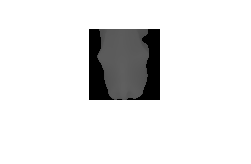

j = 2

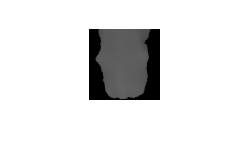

j = 3

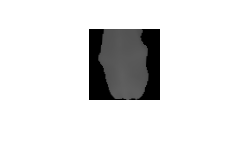

j = 4

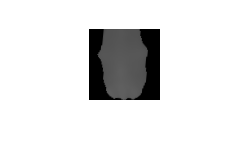

j = 5

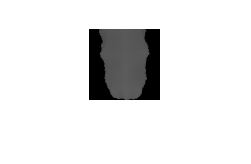

j = 6

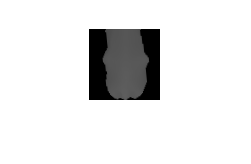

j = 7

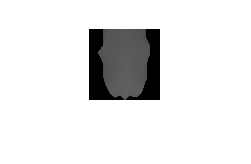

j = 8

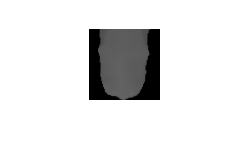

j = 9

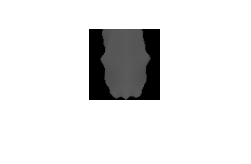

j = 10

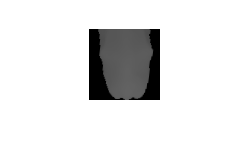

j = 11

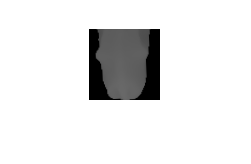

j = 12

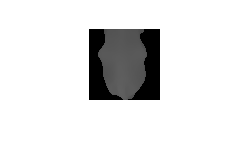

j = 13

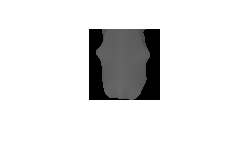

j = 14

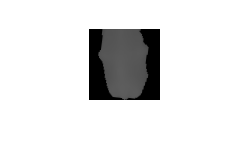

j = 15

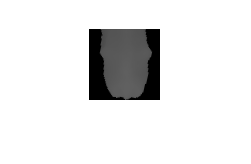

j = 16

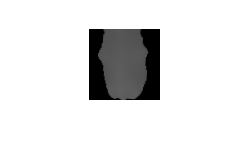

j = 17

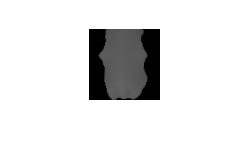

train_csv_files=get_cow_data(2,2);
for j=1:size(train_csv_files,2)
    j
    img=train_csv_files(j).data;
    figure,imshow(img)
end

**save**

csvwrite("MIGI.csv",HIDARI);
csvwrite("HIDARI.csv",MIGI);

csvwrite("backborn.csv",backborn);
csvwrite("volume.csv",V)

csvwrite("SIRI.csv",SIRI);
csvwrite("KOSI.csv",KOSI);

csvwrite("MEAN_H.csv",MEAN_H);
csvwrite("MEAN_V.csv",MEAN_V);

csvwrite("MED_H.csv",MED_H);
csvwrite("MED_V.csv",MED_V);

csvwrite("VAR_H.csv",VAR_H);
csvwrite("VAR_V.csv",VAR_V);

csvwrite("volume.csv",V)
csvwrite("label.csv",label);

**show image**

figure,imshow(IM)
hold on
    scatter(pixcel2,IN3_2(6:end-5),72,"filled","blue")
hold on
    scatter(idx,IN3,72,"filled","blue")
hold on
    scatter([ma.pix]-c(1),[1:71],"filled","red")
hold on
    scatter (ix1,[20:39],72,"filled","red")
hold on
    scatter (ix2+size(IM,2)-7,[20:39],72,"filled","red")
hold off

# **Analysis**

change_point=[];

n=2;
change_point(1)=1;
for i= 2:size(label,2)
    if label(i-1) ~= label(i)
        change_point(n)=i;
        n=n+1;
    end
end
change_point(n)=size(label,2);

clear yo_mean
clear yo_var

yo=[];
n=1;

for i=2:48
    yo=max_v(change_point(i-1):change_point(i)-1,:);
    yo_mean(n,:)=mean(yo,1);
    yo_var(n,:)=var(yo,0,1);
    n=n+1;
end
%max(yo_var)

norr=[];
for i=1:47
    norr(i)=norm(yo_mean(i,:),2);
end
jj=transpose(norr)*norr;
cos_simi=(yo_mean*transpose(yo_mean))./jj;

# **write data**

for i=383:383%205 372 383
    i
    [csv_files,name]=get_cow(i);
    inv_cow=invcow(csv_files);
    cropped=crop_cow(inv_cow);
    res=resized_cow(cropped);
    
    mkdir("../data/"+name)
        
    for j=1:size(res,2)
        csvwrite("../data/"+name+"/"+name+"_"+(j)+".csv",res(j).img);
    end
    
end